# Descriptors per cada senyal

llindar = 20;
dibuixar = false;
for senyal=0:42
    iActual = imread(strcat("Models\Meta\", int2str(senyal),'.png'));   
    iBW = imbinarize(iActual);
    iRectas = buscarRectas(iActual, false,5);
    
    pendents(senyal+1).pendientes = range([iRectas.theta]);
    pendents(senyal+1).nombre = numberToName(senyal+1);
    pendents(senyal+1).liniesParaleles = range([iRectas.theta])<= llindar;
        
    if dibuixar        
        figure 
        subplot(1,4,1)
        imshow(iActual);
        subplot(1,4,2)
        imshow(iBW(:,:,1));
        subplot(1,4,3)
        imshow(iBW(:,:,2));
        subplot(1,4,4)
        imshow(iBW(:,:,3));
    end
end

## Color

Tenim 3 grans grups de senyals segons el color, les que majoritariament son vermelles, les blaves i les blanques.

Podem definir un estadístic que ens calculi **els pixels de color vermell, blau i blanc dividit pel nombre total de píxels**, aixi podem tenir un estadístic no sensible a l'escalat. La senyal nº12 es majoritàriament groga, es pot definir també de la mateixa manera.

El valor resultant per la senyal nº12 podria ser 0 o 1 (aplicant un cert llindar) i pels demés colors un valor decimal.

## Hough

Podem aplicar la transformada de Hough per reconeixer les rectes, pero comparant el rang de les pendents de les rectes, d'aquesta manera ens permet discriminar les senyals amb linies rectes com la senyal 9 o 32.

Podem considerar aquest valor amb un llindar, 1 per valors de rang < 8 i 0 per valors superiors.

i6lines = buscarRectas(imread("Models\Meta\6.png"), false,5);
i2lines = buscarRectas(imread("Models\Meta\1.png"), false,5); %valor alto
i32lines = buscarRectas(imread("Models\Meta\32.png"), false,5);
i41lines = buscarRectas(imread("Models\Meta\41.png"), false,5);
i42lines = buscarRectas(imread("Models\Meta\42.png"), false,5);
%podem calcular el pendent de cada recta per veure quin tipus de rectes
%s'han trobat

range([i6lines.theta]);
range([i2lines.theta]);
range([i32lines.theta]);
range([i41lines.theta]);
range([i42lines.theta]);

## Forma circular, triangular, rombo

Tenim molta informació amb la forma exterior de la senyal i el seu color.

Podem detecar les figures geomètriques bàsiques amb les propietats de les regions blanques, sumat a una detecció del color ens permet:

aquesta propietat la podem emmagatzemar com un 0 o 1 directament per no arrosegar una variable categórica.

- esCercleVermell

- esRomboBlanc

- esTriangleInvertitVermell

- esRomboideBlanc

- esCercleBlanc

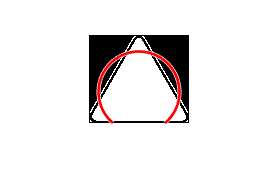

i5 = imread("Models\Meta\26.png");
BW = rgb2gray(i5);
BW = edge(BW,'canny');
BW = imfill(BW, "holes");
imshow(BW)
%no funciona imfindcircles, vamos a calcular la cirularidad:
%[centers, radii, metric]= imfindcircles(BW, [95,110],"Method","TwoStage");
%viscircles(centers, radii,'EdgeColor','b');

stats = regionprops("table", BW,"all");
[~,maxidx] = max(stats.Area);

centers = stats.Centroid; 
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2); 
radii = diameters/2;
%hay que quedarse con la circularity.!!!

hold on
viscircles(centers(maxidx,:),radii(maxidx)); 
hold off

Un circulo tiene una circularidad casi de 1.

## Detecció de formes

Algunes de les senyals tenen formes caracteristiques (com coches, camions, pas de vianants, bicicleta, etc...)

Podriem fer patter-matching per intentar buscar aquestes formes.

https://es.mathworks.com/matlabcentral/fileexchange/24925-fast-robust-template-matching

[No le veo mucho futuro.]

## Àrea i altres estadístics de la imatge binària

Per discernir entre les diferents formes, podem optar per a calcular l'àrea total dels elements interiors a la senyal i dividits pel tamany de la senyal (així no tenim problemes amb el escalat).

[ToDo: explicar "elements interiors"]

Si no tenim cap element interior, doncs la senyal tindrà un valor de 0 i podrem classificar-la com 12, 13, 15 o similar segons la seva forma.